**JPEG Compression**

The JPEG compression is a block based compression. 

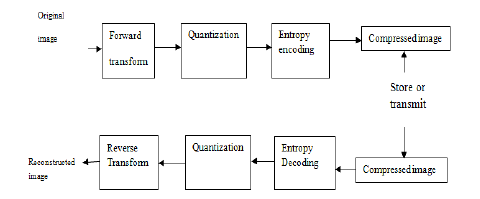

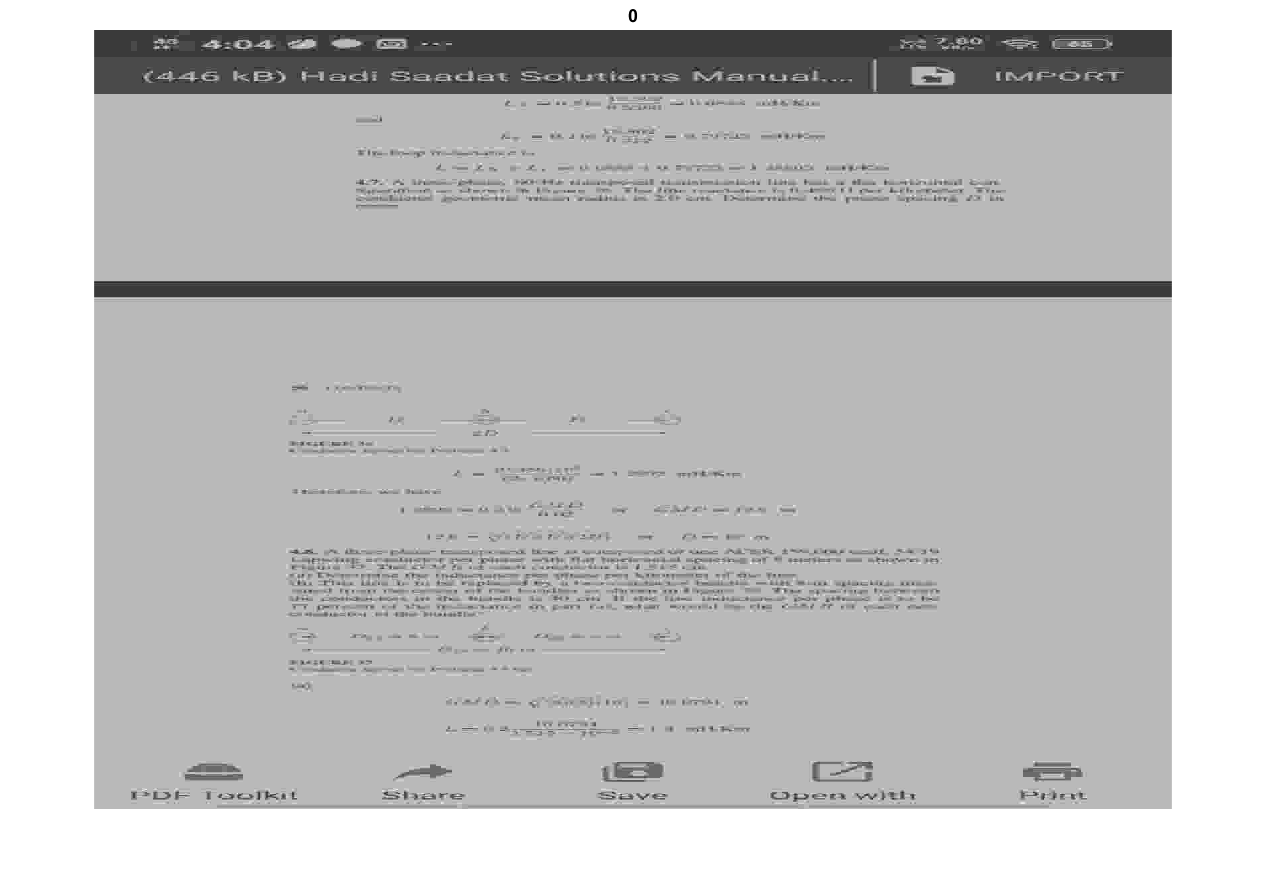

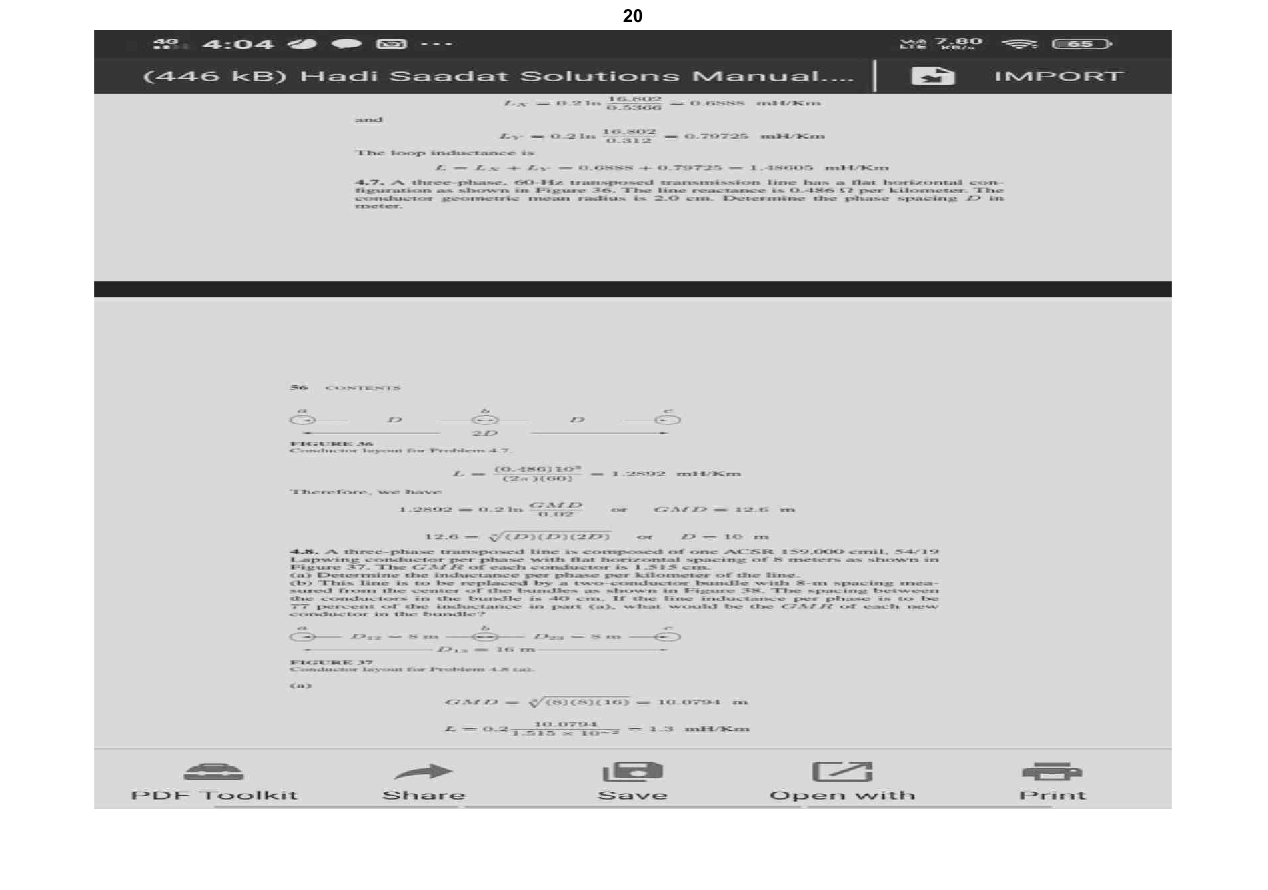

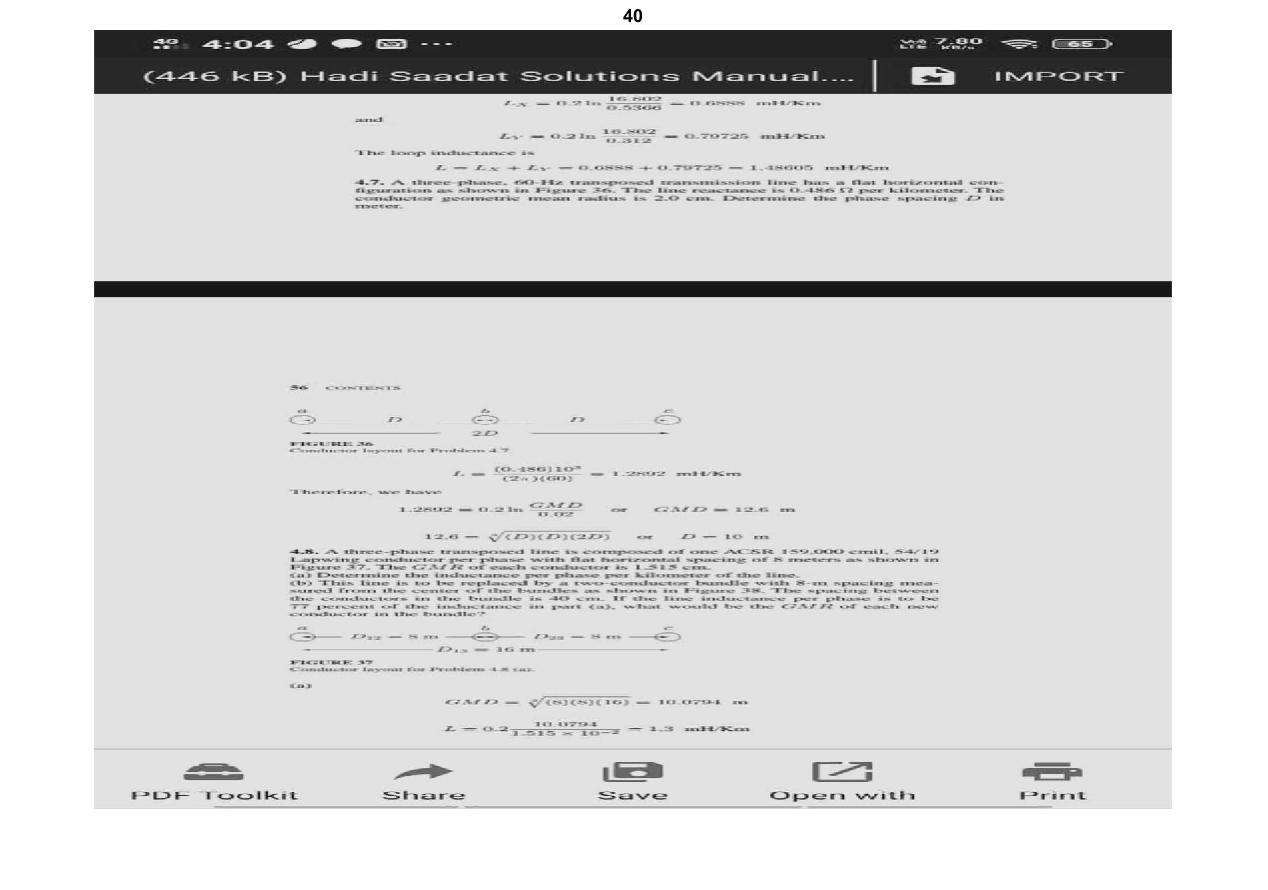

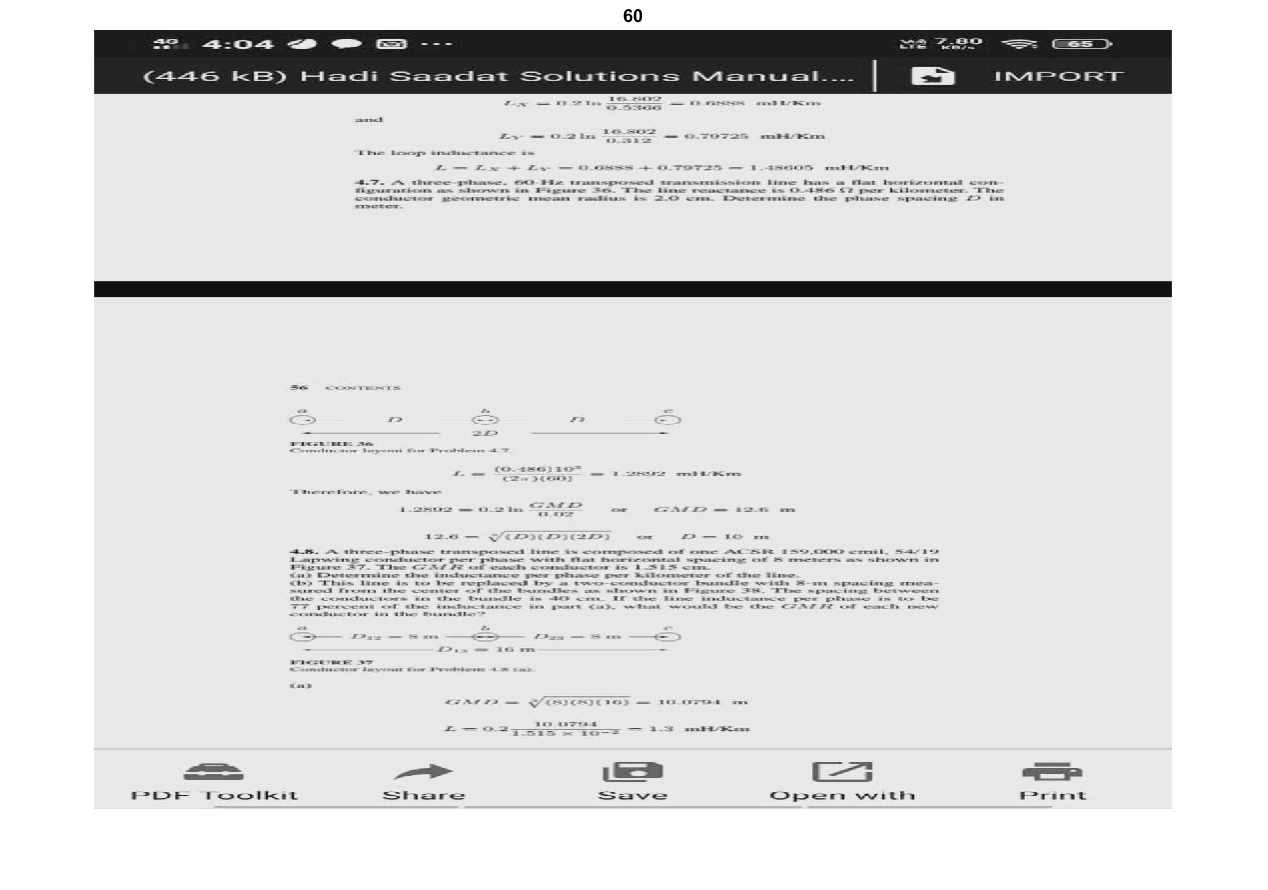

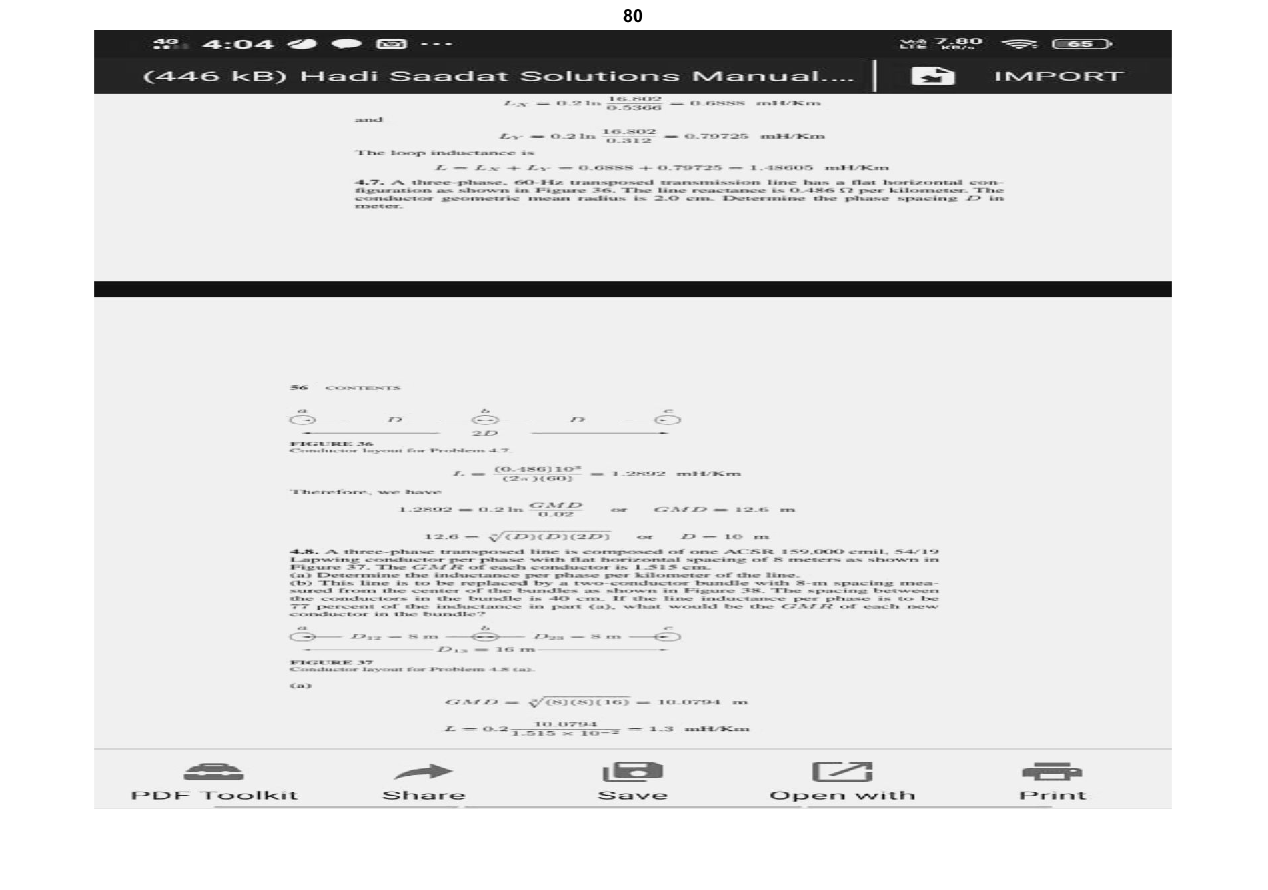

clc;  clear all;  close all;

I = imread('rev_logo.tiff'); %read image
I1=I;

[row,coln]=size(I);      %storing size of image

rem1 = rem(row,8);
row=row-rem1;

rem2 = rem(coln,8);
coln= coln-rem2;

I = imresize(I,[row coln]);
I= double(I);

%---------------------------------------------------------
% Subtracting each image pixel value by 128 
%--------------------------------------------------------
I = I - 128;
%Set the Quality of compression required
for quality =[0:20:80]
    %----------------------------------------------------------
    % Quality Matrix Formulation
    %----------------------------------------------------------
    Q50 = [ 16 11 10 16 24 40 51 61;
         12 12 14 19 26 58 60 55;
         14 13 16 24 40 57 69 56;
         14 17 22 29 51 87 80 62; 
         18 22 37 56 68 109 103 77;
         24 35 55 64 81 104 113 92;
         49 64 78 87 103 121 120 101;
         72 92 95 98 112 100 103 99];
     
     if quality > 50
         QX = round(Q50.*(ones(8)*((100-quality)/50)));
         QX = uint8(QX);
     elseif quality < 50
         QX = round(Q50.*(ones(8)*(50/quality)));
         QX = uint8(QX);
     elseif quality == 50
         QX = Q50;
     end
     
      
    %----------------------------------------------------------
    % Formulation of forward DCT Matrix and inverse DCT matrix
    %----------------------------------------------
    DCT_matrix8 = dct(eye(8));
    iDCT_matrix8 = DCT_matrix8';   %inv(DCT_matrix8);
    %----------------------------------------------------------
    % Jpeg Compression
    %----------------------------------------------------------
    dct_restored = zeros(row,coln);
    QX = double(QX);
    %----------------------------------------------------------
    % Jpeg Encoding
    %----------------------------------------------------------
    %----------------------------------------------------------
    % Forward Discret Cosine Transform
    %----------------------------------------------------------
    for i1=[1:8:row]
        for i2=[1:8:coln]
            zBLOCK=I(i1:i1+7,i2:i2+7);
            win1=DCT_matrix8*zBLOCK*iDCT_matrix8;
            dct_domain(i1:i1+7,i2:i2+7)=win1;
        end
    end
    
    %-----------------------------------------------------------
    % Quantization of the DCT coefficients
    %-----------------------------------------------------------
    for i1=[1:8:row]
        for i2=[1:8:coln]
            win1 = dct_domain(i1:i1+7,i2:i2+7);
            win2=round(win1./QX);
            dct_quantized(i1:i1+7,i2:i2+7)=win2;
        end
    end
    
    compresed_img=dct_quantized;
    
    %-----------------------------------------------------------
    % Huffman encoding
    %-----------------------------------------------------------
    %function which converts array to vector
    [m,n]=size(compresed_img);
    vec_size = 1;
    for p = 1:m
    for q = 1:n
    newvec(vec_size) = compresed_img(p,q);
    vec_size = vec_size+1;
    end
    end
    symbols = unique(newvec(:));
    counts = hist(newvec(:), symbols);
    p = double(counts) ./ sum(counts);
    
    [dict,~] = huffman_dict(symbols,p);
    
    hcode = huffman_encode(symbols,dict,newvec(:));
    
    
    %-----------------------------------------------------------
    % Huffman Decoding
    %-----------------------------------------------------------
    dhsig = huffman_decode(symbols,dict,hcode);
    
    %vector to array conversion
    dec_row=sqrt(length(dhsig));
    dec_col=dec_row;
    %variables using to convert vector 2 array
    arr_row = 1;
    arr_col = 1;
    vec_si = 1;
    for x = 1:m
    for y = 1:n
    back(x,y)=dhsig(vec_si);
    arr_col = arr_col+1;
    vec_si = vec_si + 1;
    end
    arr_row = arr_row+1;
    end

    %-----------------------------------------------------------
    % Jpeg Decoding 
    %-----------------------------------------------------------
    % Dequantization of DCT Coefficients
    %-----------------------------------------------------------
    for i1=[1:8:row]
        for i2=[1:8:coln]
            win2 = back(i1:i1+7,i2:i2+7);
            win3 = win2.*QX;
            dct_dequantized(i1:i1+7,i2:i2+7) = win3;
        end
    end
    
        
    
    %-----------------------------------------------------------
    % Inverse DISCRETE COSINE TRANSFORM
    %-----------------------------------------------------------
    for i1=[1:8:row]
        for i2=[1:8:coln]
            win3 = dct_dequantized(i1:i1+7,i2:i2+7);
            win4=iDCT_matrix8*win3*DCT_matrix8;
            dct_restored(i1:i1+7,i2:i2+7)=win4;
        end
    end
    I2=dct_restored;
    % ---------------------------------------------------------
    % Conversion of Image Matrix to Intensity image
    %----------------------------------------------------------
    K=mat2gray(I2);
    %----------------------------------------------------------
    %Display of Results
    %----------------------------------------------------------
    %figure();imshow(compresed_img);ylabel('Dct Points');
    figure();imshow(K);title(quality);

end